% syms s t;
s = tf('s');

student_num = [3 8 1 1 3 5 4 4];
sn_A = student_num(1) + 10;
sn_B = student_num(2) + 10;
sn_C = student_num(3) + 10;
sn_D = student_num(4) + 10;
sn_E = student_num(5) + 10;
sn_F = student_num(6) + 10;
sn_G = student_num(7) + 10;
sn_H = student_num(8) + 10;

% given
JG = sn_A*75*1e-10;
JF = sn_B*25*1e-10;
JL = 60*1e-10;

BG = sn_C*2*1e-7;
BF = sn_D*400*1e-10;
BL = 500*1e-10;

KG = sn_E*3000*1e-4;
KF = sn_F*1800*1e-4;
KL = 2500*1e-4;

JM = 1.03*1e-7; % datasheet gave g*cm^2, converted to kg*m^2
BM = 0;
tauM = 1;


% convert these to the fucking electric ones kms

CG = JG;
CF = JF;
CL = JL;

RG = 1/BG;
RF = 1/BF;
RL = 1/BL;
RM = 1/BM;

LG = 1/KG;
LF = 1/KF;
LL = 1/KL;

CM = JM;
IM = tauM;

mat11 = CM*s+1/(LG*s)+1/RG;
mat22 = CG*s+1/RG+1/(LG*s)+1/RF+1/(LF*s);
mat33 = CF*s+CL*s+1/RF+1/(LF*s)+1/(LL*s)+1/RL;

mat12 = -1/RG-1/(LG*s);
mat13 = 0;

mat23 = -1/RF-1/(LF*s);

Y = [mat11, mat12, mat13;  
     mat12, mat22, mat23; 
     mat13, mat23, mat33] 

Y =
 
  From input 1 to output...
       2.641e-08 s^2 + 5.641e-07 s + 1
   1:  -------------------------------
                  0.2564 s
 
       -5.641e-07 s - 1
   2:  ----------------
           0.2564 s
 
   3:  0
 
  From input 2 to output...
       -5.641e-07 s - 1
   1:  ----------------
           0.2564 s
 
       9.259e-09 s^3 + 2.507e-07 s^2 + 0.6268 s
   2:  ----------------------------------------
                     0.09497 s^2
 
       -1.63e-07 s - 1
   3:  ---------------
          0.3704 s
 
  From input 3 to output...
   1:  0
 
       -1.63e-07 s - 1
   2:  ---------------
          0.3704 s
 
       7.556e-08 s^3 + 7.259e-07 s^2 + 4.37 s
   3:  --------------------------------------
                     1.481 s^2
 
Continuous-time transfer function.



     

Z = inv(Y);

I = [IM; 0; 0];

V = Z*I;
Vm = V(1);
VG = V(2);
VF = V(3);
VL = VF;

xfer = minreal(Vm/IM);

[num, den] = tfdata(xfer,'v');
P3_Ym = tf(num, den)

P3_Ym =
 
  9.709e06 s^6 + 3.562e08 s^5 + 1.219e15 s^4 + 1.688e16 s^3 + 2.378e22 s^2 - 1.134e10 s + 0.0001426
  -------------------------------------------------------------------------------------------------
  s^7 + 58.04 s^6 + 1.634e08 s^5 + 4.1e09 s^4 + 5.688e15 s^3 + 4.765e15 s^2 + 5.14e21 s + 1.532e10
 
Continuous-time transfer function.



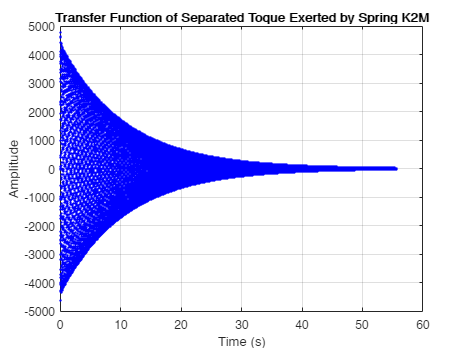

[y, t] = step(xfer);
plot(t, y, ".", 'LineWidth', 0.1, 'Color','Blue')

grid on
title("Transfer Function of Separated Toque Exerted by Spring K2M")
xlabel("Time (s)")
ylabel("Amplitude")
hold off

% integrate to get angles from angular vel (voltages)

stall_torque = 11.2/2*(1e-3) % datasheet gives milli Nm

stall_torque = 0.0056

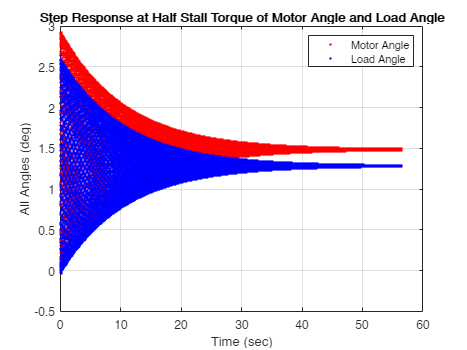

% I_stall = [stall_torque; 0; 0];
% V_stall = Z*I_stall;
% 
% Vm_stall = V(1);
% VG_stall = V(2);
% VF_stall = V(3);
% VL_stall = VF_stall;

wM = Vm;

opt = stepDataOptions('StepAmplitude',stall_torque);
xfer_M = minreal(wM/s);

[num_M, den_M] = tfdata(xfer_M,'v');
[y_M, t_M] = step(xfer_M, opt);
plot(t_M, y_M*180/pi, '.', 'LineWidth', 0.01, 'Color','Red')

grid on
xlabel("Time (sec)")
ylabel("All Angles (deg)")
% axis([0, 24, 0, 1.2])

hold on 
wL = VL;

xfer_L = minreal(wL/s);

[num_L, den_L] = tfdata(xfer_L,'v');
[y_L, t_L] = step(xfer_L, opt);
plot(t_L, y_L*180/pi, '.', 'LineWidth', 0.01, 'Color','Blue')

grid on
title("Step Response at Half Stall Torque of Motor Angle and Load Angle")
legend("Motor Angle", "Load Angle")